%% 小波变换与STFT时频分析对比 - MATLAB实现（独立图形版本）
clear; close all; clc;

%% 参数设置
fs = 1000;  % 采样频率
t = 0:1/fs:3-1/fs;  % 3秒时间向量

%% 生成测试信号 - 只使用signal1，不加噪声
% 信号1: 分段正弦波
signal1 = zeros(size(t));
signal1(t < 1) = sin(2*pi*10*t(t < 1));        % 0-1秒: 10Hz
signal1(t >= 1 & t < 2) = sin(2*pi*25*t(t >= 1 & t < 2)); % 1-2秒: 25Hz
signal1(t >= 2) = sin(2*pi*50*t(t >= 2));      % 2-3秒: 50Hz

%% 小波变换分析
fprintf('开始小波变换分析...\n');

开始小波变换分析...


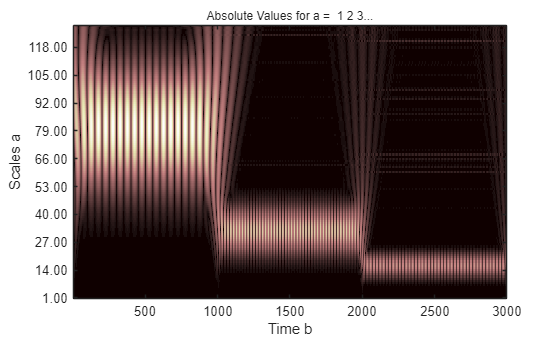


% 使用MATLAB的连续小波变换
scales = 1:1:128; 
[cwt_coeffs, frequencies] = cwt(signal1, scales, 'morl', 'SamplingFrequency', fs);

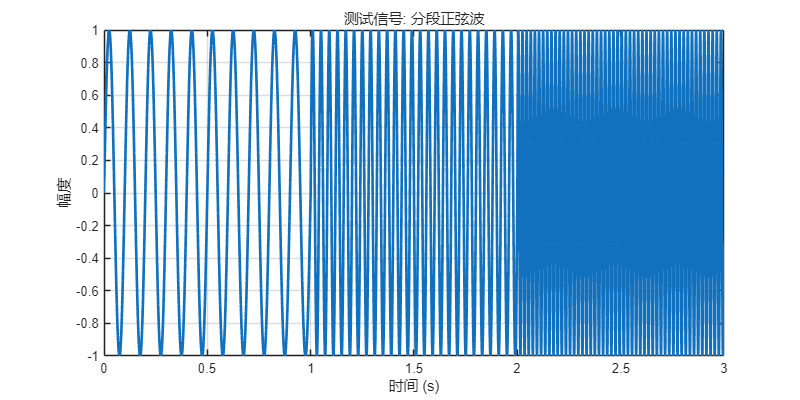



% 确保数据维度匹配
frequencies = frequencies(:);  % 确保是列向量
cwt_abs = abs(cwt_coeffs);

%% STFT分析函数
function [f, t_stft, Zxx] = stft_analysis(signal_data, window_type, window_size, fs, overlap_ratio)
    % STFT分析函数
    noverlap = round(window_size * overlap_ratio);
    
    switch window_type
        case 'hann'
            window = hann(window_size);
        case 'hamming'
            window = hamming(window_size);
        case 'blackman'
            window = blackman(window_size);
        otherwise % rectangular
            window = rectwin(window_size);
    end
    
    [Zxx, f, t_stft] = spectrogram(signal_data, window, noverlap, window_size, fs);
end

%% 1. 绘制原始信号
figure('Position', [100, 100, 800, 400], 'Name', '原始信号');
plot(t, signal1,'LineWidth', 2);
title('测试信号: 分段正弦波');
xlabel('时间 (s)');
ylabel('幅度');
grid on;

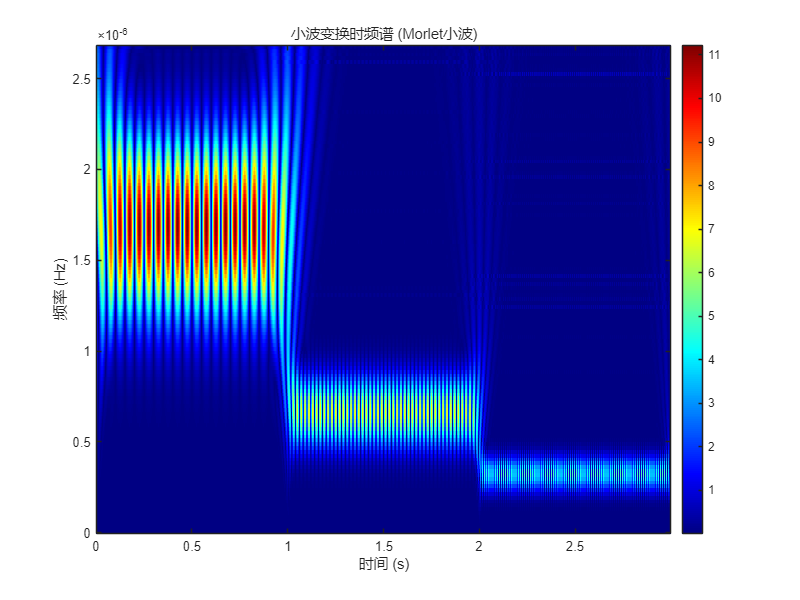


%% 2. 绘制小波变换二维时频图
figure('Position', [100, 100, 800, 600], 'Name', '小波变换二维时频图');
imagesc(t, frequencies, cwt_abs);
set(gca, 'YDir', 'normal');
title('小波变换时频谱 (Morlet小波)');
xlabel('时间 (s)');
ylabel('频率 (Hz)');
colorbar;
colormap(jet);

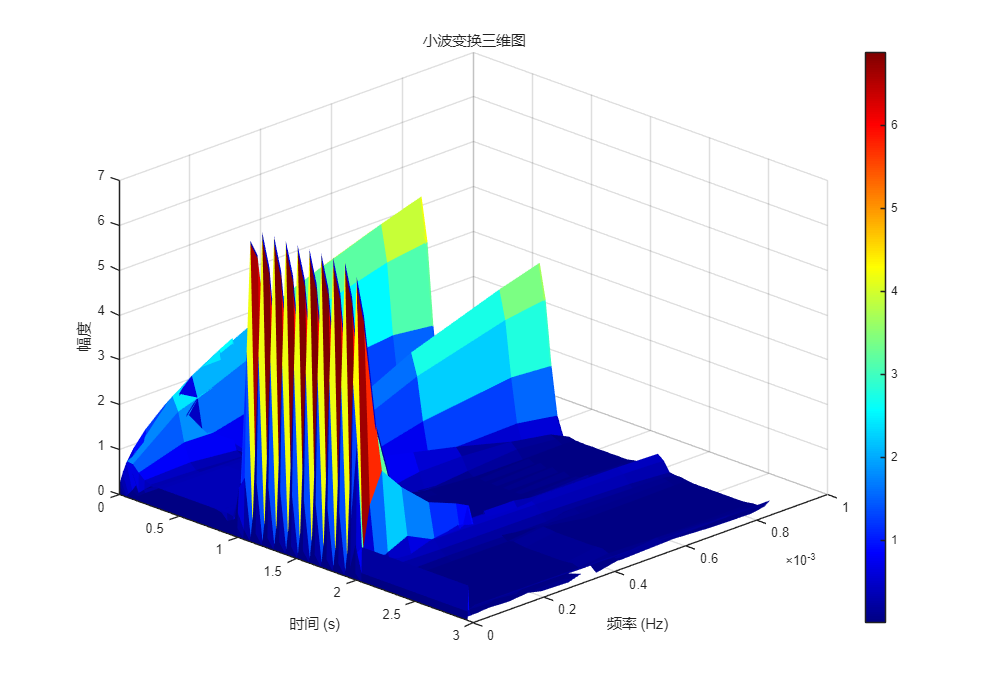


%% 3. 绘制小波变换三维图
figure('Position', [100, 100, 1000, 700], 'Name', '小波变换三维图');
% 对数据进行降采样以改善三维图显示
num_freq = size(cwt_abs, 1);
num_time = size(cwt_abs, 2);

% 安全地选择降采样索引
t_downsample = 1:min(50, floor(num_time/10)):num_time;
f_downsample = 1:min(5, floor(num_freq/5)):num_freq;

% 创建网格
[t_grid, f_grid] = meshgrid(t(t_downsample), frequencies(f_downsample));

% 提取对应的幅度值
amplitude = cwt_abs(f_downsample, t_downsample);

% 绘制三维图
surf(t_grid, f_grid, amplitude, 'EdgeColor', 'none');
title('小波变换三维图');
xlabel('时间 (s)');
ylabel('频率 (Hz)');
zlabel('幅度');
colorbar;
colormap(jet);
view(45, 30);

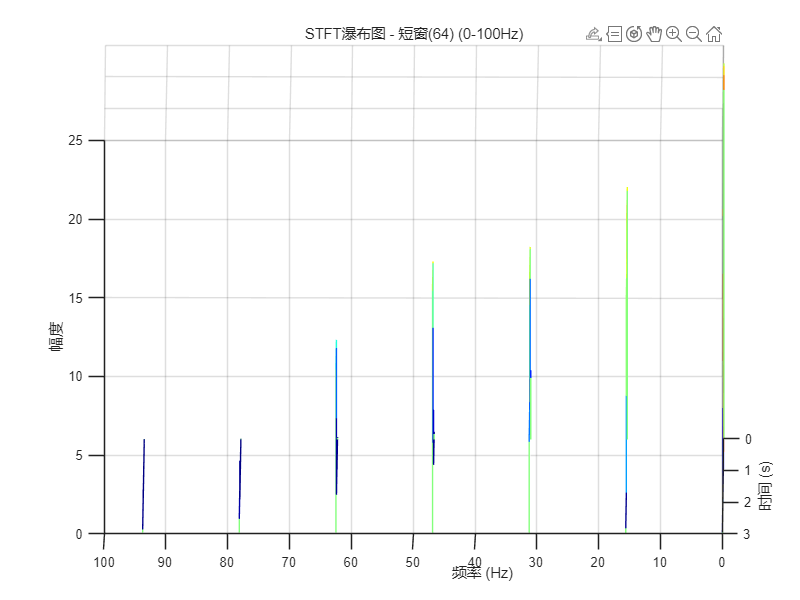

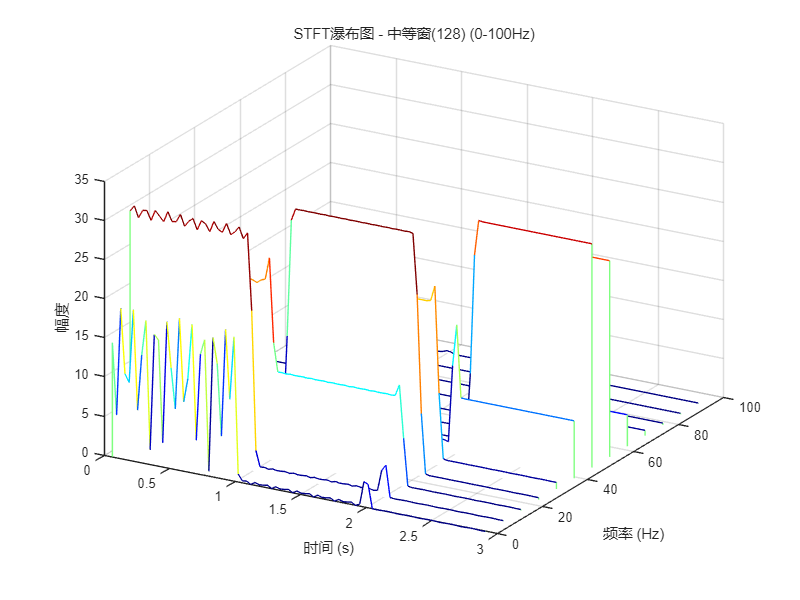

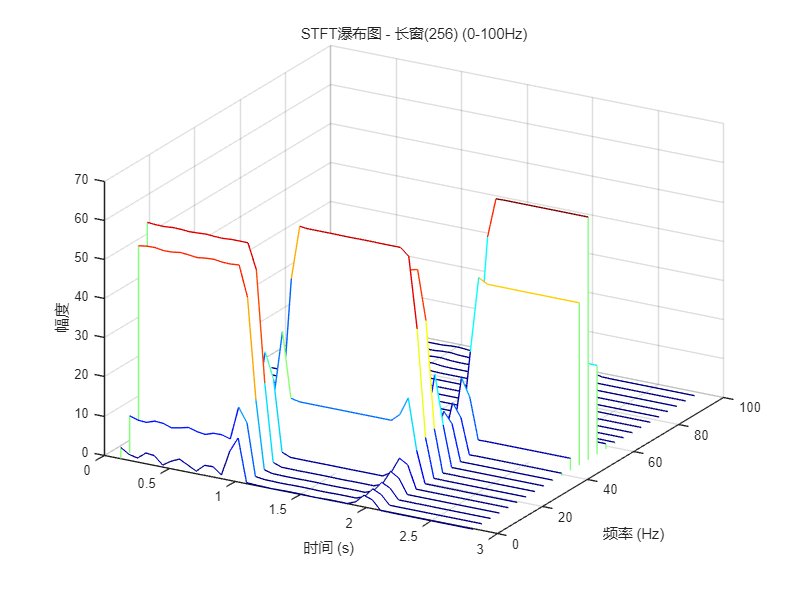

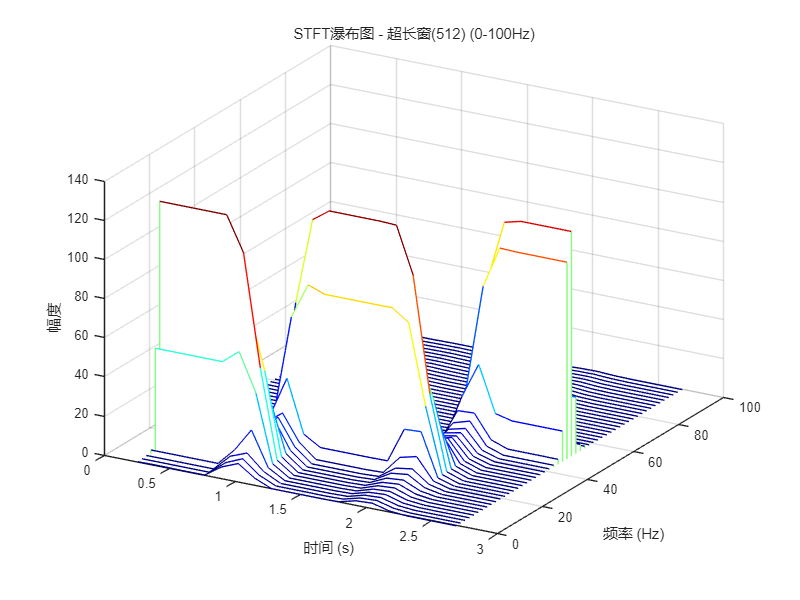


%% 4. 绘制不同窗长的STFT对比 - 使用瀑布图方法
window_sizes = [64, 128, 256, 512];
window_names = {'短窗(64)', '中等窗(128)', '长窗(256)', '超长窗(512)'};
max_freq = 100; % 设置最大显示频率为100Hz

for i = 1:length(window_sizes)
    figure('Position', [100+100*i, 100, 800, 600], 'Name', sprintf('STFT-窗长%d', window_sizes(i)));
    
    % 方法1：修改STFT分析函数调用，添加频率限制参数
    [f, t_stft, Zxx] = stft_analysis(signal1, 'hann', window_sizes(i), fs, 0.75);
    
    % 使用瀑布图展示STFT结果
    waterfall(t_stft, f, abs(Zxx));
    title(sprintf('STFT瀑布图 - %s (0-100Hz)', window_names{i}));
    xlabel('时间 (s)');
    ylabel('频率 (Hz)');
    zlabel('幅度');
    colormap(jet);
    view(30, 30);
    grid on;
    
    % 方法2：直接设置y轴范围限制
    ylim([0, max_freq]);
end

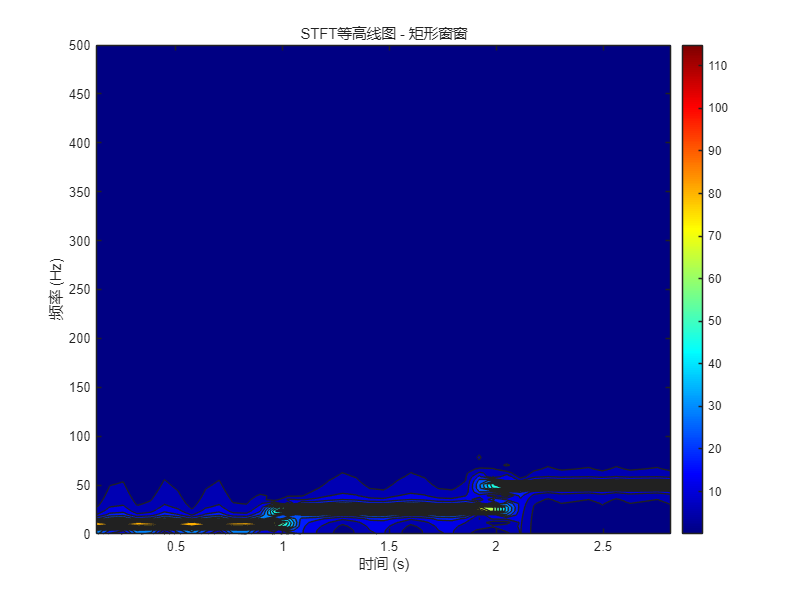

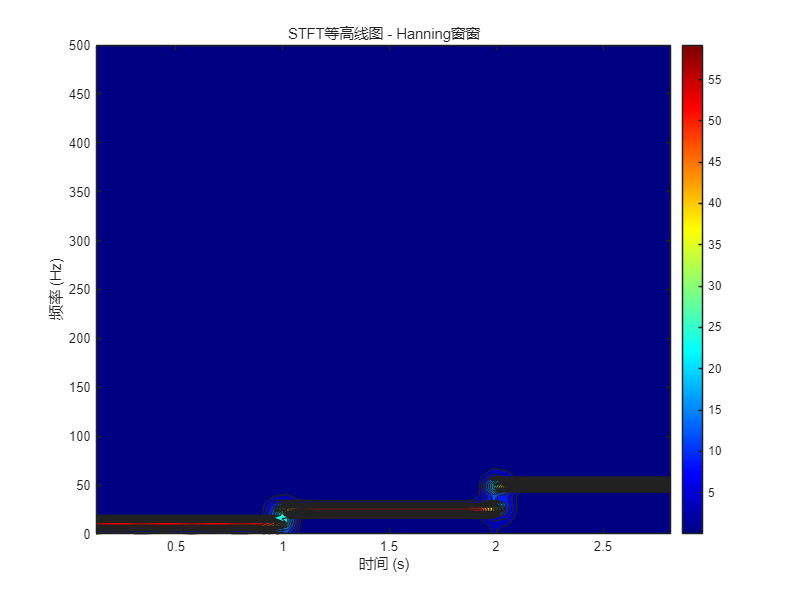

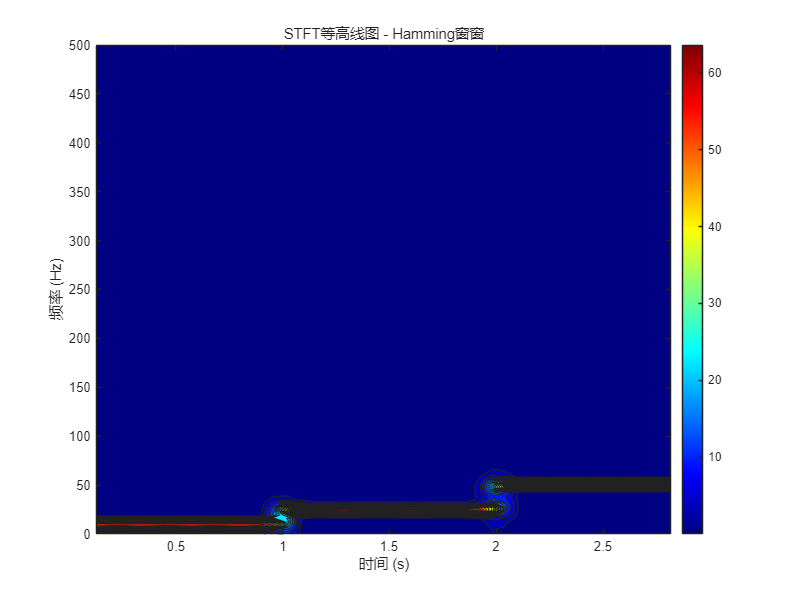

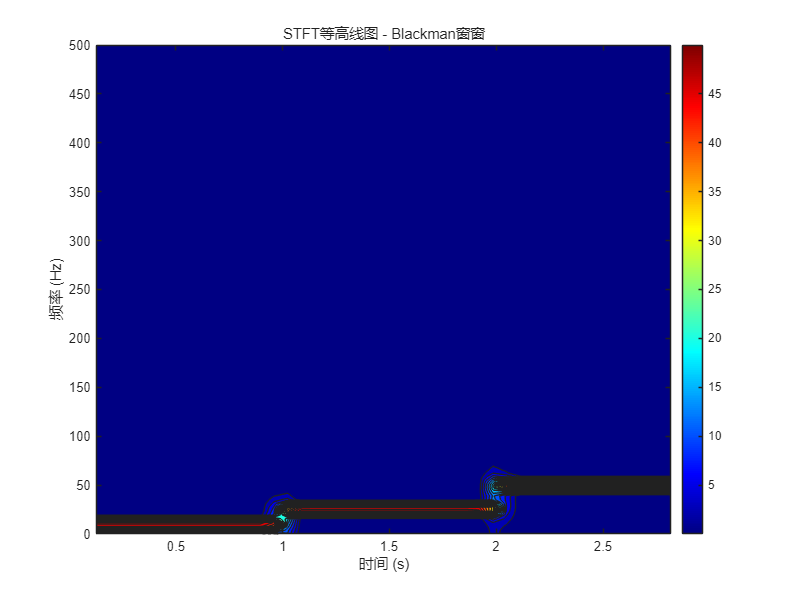


%% 5. 绘制不同窗函数的STFT对比 - 使用等高线图方法
window_types = {'rectangular', 'hann', 'hamming', 'blackman'};
window_names = {'矩形窗', 'Hanning窗', 'Hamming窗', 'Blackman窗'};

for i = 1:length(window_types)
    figure('Position', [100+100*i, 200, 800, 600], 'Name', sprintf('STFT-%s窗', window_names{i}));
    
    [f, t_stft, Zxx] = stft_analysis(signal1, window_types{i}, 256, fs, 0.75);
    
    % 使用等高线图展示STFT结果
    contourf(t_stft, f, abs(Zxx), 20); % 20个等高线级别
    title(sprintf('STFT等高线图 - %s窗', window_names{i}));
    xlabel('时间 (s)');
    ylabel('频率 (Hz)');
    colorbar;
    colormap(jet);
end

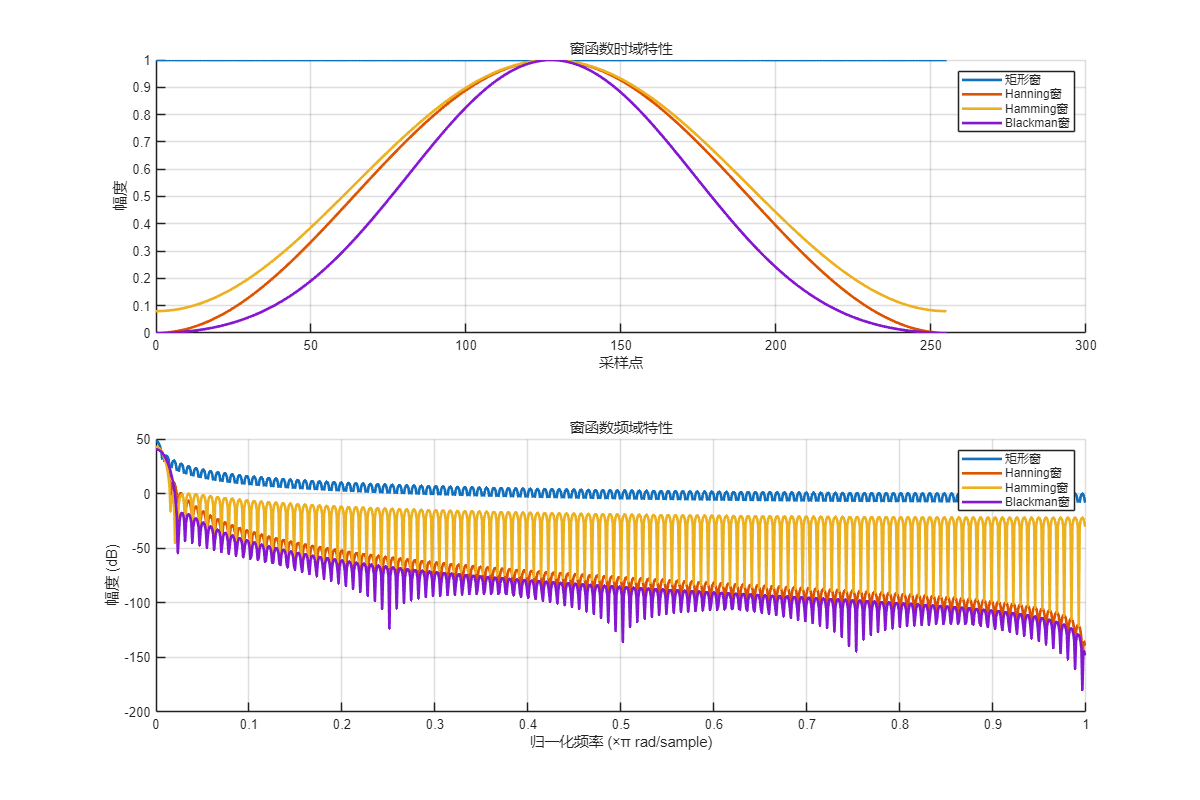


%% 6. 绘制窗函数特性对比图
figure('Position', [100, 100, 1200, 800], 'Name', '窗函数特性对比');

% 绘制不同窗函数的时域特性
subplot(2, 1, 1);
window_len = 256;
t_win = (0:window_len-1)';

windows = {rectwin(window_len), hann(window_len), hamming(window_len), blackman(window_len)};
window_names_full = {'矩形窗', 'Hanning窗', 'Hamming窗', 'Blackman窗'};

hold on;
for i = 1:length(windows)
    plot(t_win, windows{i}, 'LineWidth', 2, 'DisplayName', window_names_full{i});
end
hold off;
title('窗函数时域特性');
xlabel('采样点');
ylabel('幅度');
legend('show');
grid on;

% 绘制不同窗函数的频域特性
subplot(2, 1, 2);
hold on;
for i = 1:length(windows)
    [h, w] = freqz(windows{i}, 1, 1024);
    plot(w/pi, 20*log10(abs(h)), 'LineWidth', 2, 'DisplayName', window_names_full{i});
end
hold off;
title('窗函数频域特性');
xlabel('归一化频率 (×π rad/sample)');
ylabel('幅度 (dB)');
legend('show');
grid on;

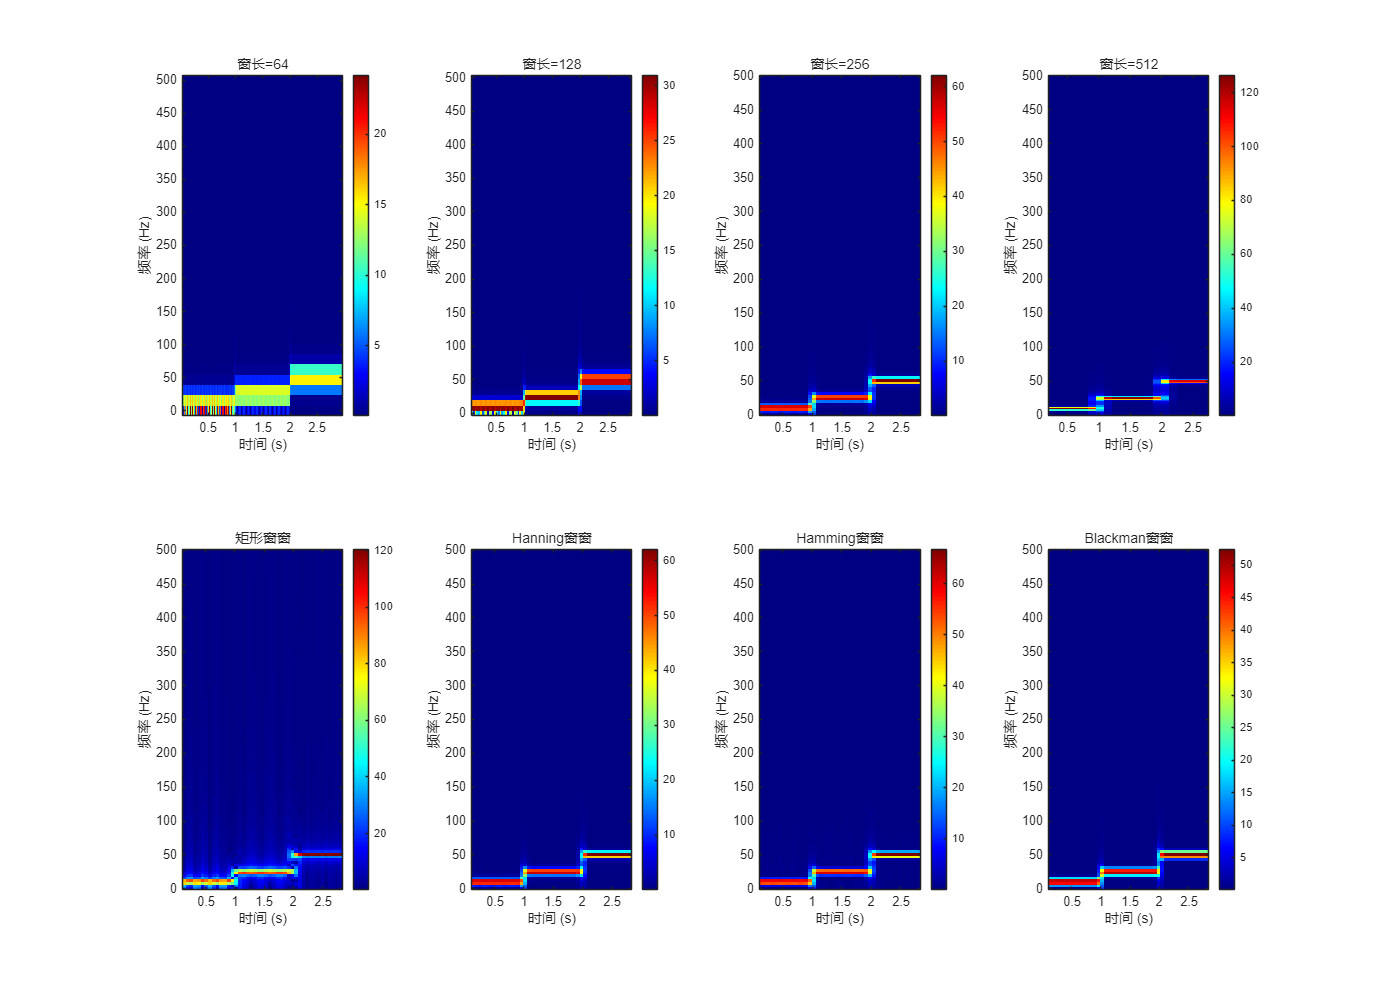


%% 7. 绘制分辨率对比图 - 使用子图但每个子图独立清晰
figure('Position', [100, 100, 1400, 1000], 'Name', '分辨率对比');

% 不同窗长的分辨率对比
for i = 1:length(window_sizes)
    subplot(2, 4, i);
    [f, t_stft, Zxx] = stft_analysis(signal1, 'hann', window_sizes(i), fs, 0.75);
    
    imagesc(t_stft, f, abs(Zxx));
    set(gca, 'YDir', 'normal');
    title(sprintf('窗长=%d', window_sizes(i)));
    xlabel('时间 (s)');
    ylabel('频率 (Hz)');
    colorbar;
    colormap(jet);
end

% 不同窗函数的分辨率对比
for i = 1:length(window_types)
    subplot(2, 4, i+4);
    [f, t_stft, Zxx] = stft_analysis(signal1, window_types{i}, 256, fs, 0.75);
    
    imagesc(t_stft, f, abs(Zxx));
    set(gca, 'YDir', 'normal');
    title(sprintf('%s窗', window_names{i}));
    xlabel('时间 (s)');
    ylabel('频率 (Hz)');
    colorbar;
    colormap(jet);
end


fprintf('分析完成！共生成 %d 个独立图形\n', 1 + 1 + 1 + 4 + 4 + 1 + 1);

分析完成！共生成 13 个独立图形
